## 1.相似性矩阵绘制

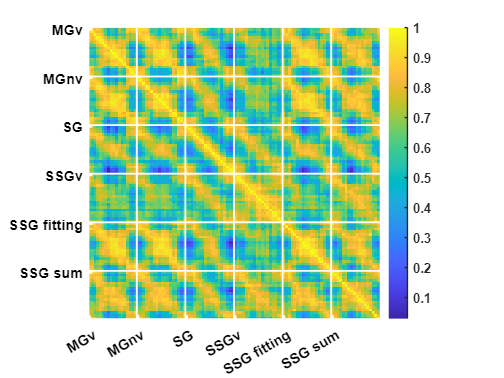

t = 20;
similarity_at_t = similarity_matrix(:, :, t);

figure;

imagesc(similarity_at_t);
colorbar;
% clim([-1, 1]);                                  % bar范围
hold on;

% 设置坐标轴刻度和标签
num_repeats = size(similarity_at_t, 1);
group_size = 18;                                % 每 18 个 repeat 为一组
xticks(1:group_size:num_repeats);
yticks(1:group_size:num_repeats);
conditionlabel = {'MGv','MGnv','SG','SSGv','SSG fitting','SSG sum'};
xticklabels(arrayfun(@(x) sprintf('%s', conditionlabel{floor(x/18)+1}), 1:group_size:num_repeats, 'UniformOutput', false));
yticklabels(arrayfun(@(x) sprintf('%s', conditionlabel{floor(x/18)+1}), 1:group_size:num_repeats, 'UniformOutput', false));

% 分割线
for i = 1:group_size:num_repeats
    
    line([i-0.5, i-0.5], [0.5, num_repeats+0.5], 'Color', 'w', 'LineWidth', 1.5);
    
    line([0.5, num_repeats+0.5], [i-0.5, i-0.5], 'Color', 'w', 'LineWidth', 1.5);
end


% title(sprintf('Similarity Matrix at Time Point %d', t));
% xlabel('Repeat Group');
% ylabel('Repeat Group');


axis square; 

set(gca, 'FontSize', 10,'Box','off'); 
ax = gca;
ax.XAxis.Color = 'white';  % X轴（底部）颜色
ax.YAxis.Color = 'white';  % Y轴（左侧）颜色
ax.XAxis.TickLabelColor = 'black';  % X轴刻度标签颜色
ax.YAxis.TickLabelColor = 'black';  % Y轴刻度标签颜色
ax.LineWidth = 2;

ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;
ax.XAxis.FontWeight = 'bold';

h = colorbar;
h.Box = "off";

## 2.MDS

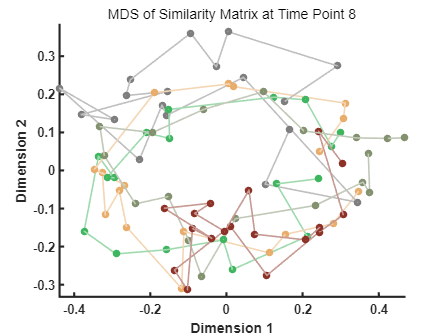

t = 8;
similarity_at_t = similarity_matrix(:, :, t);

% 非负的距离矩阵
distance_matrix = 1 - similarity_at_t; 

distance_matrix = max(distance_matrix, distance_matrix');           % 确保对称
distance_matrix = max(distance_matrix, 0);                          % 确保非负


[Y, stress] = mdscale(distance_matrix, 3);                                    % 降维到二维



num_repeats = size(Y, 1);
group_size = 18; 
num_groups = ceil(num_repeats / group_size);
colors = [62,181,95;233,173,107;131,145,111;142,50,40;126,126,126]/255;

% 蓝-EC；红-EC0；黄-SC；绿-patchsum；紫-patchcenter

% 绘制 MDS 
figure;
hold on;
for g = 1:5
    
    group_indices = (g-1)*group_size + 1 : min(g*group_size, num_repeats);

    % scatter(Y(group_indices, 1), Y(group_indices, 2), 50, colors(g, :), 'filled');
    scatter3(Y(group_indices, 1), Y(group_indices, 2), Y(group_indices, 3), ...
        50, colors(g, :), 'filled');
    
    light_color = colors(g, :) + (1 - colors(g, :)) * 0.5;          % 将颜色变浅
    % plot(Y(group_indices, 1), Y(group_indices, 2), '-', 'Color', light_color, 'LineWidth', 1.5);
    plot3(Y(group_indices, 1), Y(group_indices, 2), Y(group_indices, 3), ...
        '-', 'Color', light_color, 'LineWidth', 1.5);
    
end
title(sprintf('MDS of Similarity Matrix at Time Point %d', t));
xlabel('Dimension 1');
ylabel('Dimension 2');


% repeat 编号
% for i = 1:size(Y, 1)
%     text(Y(i, 1), Y(i, 2), sprintf('%d', i), ...
%         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
% end


axis equal; 
set(gca, 'FontSize', 10);
zlabel('Dimension 3');

ax = gca;
ax.LineWidth = 2;

ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;
ax.XAxis.FontWeight = 'bold';

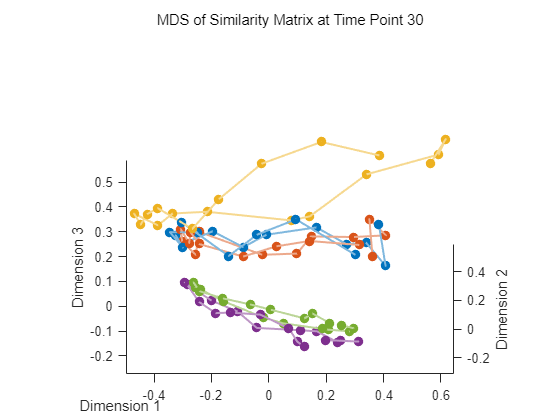


view(3);
output_filename = 'rotation_animation.gif'; % 输出文件名
angle_step = 5; % 每帧旋转的角度
num_frames = 360 / angle_step; % 总帧数
for i = 1:num_frames
    % 更新视角
    view(angle_step * i, 30); % 30 是俯仰角，可以调整
    drawnow; % 刷新图形
    
    % 捕获当前帧
    frame = getframe(gcf);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    
    % 保存为 GIF
    if i == 1
        imwrite(imind, cm, output_filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.1);
    else
        imwrite(imind, cm, output_filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.1);
    end
end


disp(['动图已保存为: ', output_filename]);

动图已保存为: rotation_animation.gif


## 3.timebin

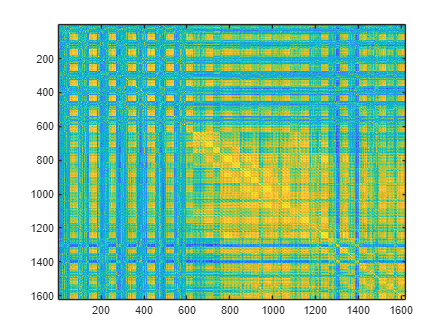

figure;
imagesc(correlation_matrix_timebin);

% 假设 similarity_matrix 是 1620×1620 的相似性矩阵
% similarity_matrix = rand(1620, 1620); % 示例数据

% 数据参数
num_points = 1620; % 总点数
group_size = 18; % 每组 18 个点
num_groups = 5; 
num_time_points = 18; % 18 个时间点

% 将相似性矩阵转换为距离矩阵
distance_matrix = 1 - correlation_matrix_timebin; % 相似性越高，距离越近
distance_matrix = max(distance_matrix, distance_matrix'); % 确保对称
distance_matrix = max(distance_matrix, 0); % 确保非负

% 使用 MDS 将距离矩阵降维到三维空间
Y = mdscale(distance_matrix, 3); % Y 是 1620×3 的矩阵


% 初始化存储每组中心点的矩阵
% center_points 是 90×3×18 的矩阵
center_points = zeros(num_groups, 3, num_time_points);

% 计算每组在每个时间点的中心点
for t = 1:num_time_points
    % 提取当前时间点的数据
    start_idx = (t-1) * num_groups * group_size + 1;
    end_idx = t * num_groups * group_size;
    current_time_data = Y(start_idx:end_idx, :); % 当前时间点的数据
    
    % 计算每组中心点
    for g = 1:num_groups
        group_indices = (g-1)*group_size + 1 : g*group_size;
        
        % center_points(g, :, t) = mean(current_time_data(group_indices, :), 1);        % 计算均值
        center_points(g, :, t) = mean(current_time_data(group_indices, :), 1);          % 计算某个位置
    end
end

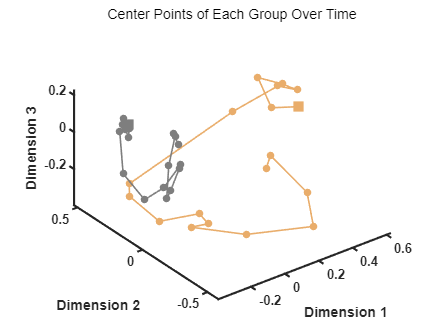


% 绘制三维图
figure;
hold on;
colors = [62,181,95;233,173,107;131,145,111;142,50,40;126,126,126]/255;

pointidxs = 1:18;
for g = [2,5]
    % 提取当前组的中心点
    group_centers = squeeze(center_points(g, :, :))'; % 大小为 18×3

    for pointidx = pointidxs
        % 绘制中心点
        if pointidx ==pointidxs(1)
            scatter3(group_centers(pointidx, 1), group_centers(pointidx, 2), group_centers(pointidx, 3), ...
                150, colors(g, :), 'filled','Marker','square');
        else
            scatter3(group_centers(pointidx, 1), group_centers(pointidx, 2), group_centers(pointidx, 3), ...
                50, colors(g, :), 'filled');
        end        
    end
    % 连接中心点
    plot3(group_centers(pointidxs, 1), group_centers(pointidxs, 2), group_centers(pointidxs, 3), ...
            '-', 'Color', colors(g, :), 'LineWidth', 1.5);
    
end

% 美化图形
grid off;
axis equal;
set(gca, 'FontSize', 10);
view(3); % 设置三维视角

% 添加标题和标签
title('Center Points of Each Group Over Time');
xlabel('Dimension 1');
ylabel('Dimension 2');
zlabel('Dimension 3');
% legend(arrayfun(@(g) sprintf('Group %d', g), 1:num_groups, 'UniformOutput', false));

axis equal; 
set(gca, 'FontSize', 10);
zlabel('Dimension 3');
ax = gca;
ax.LineWidth = 2;

ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;
ax.XAxis.FontWeight = 'bold';

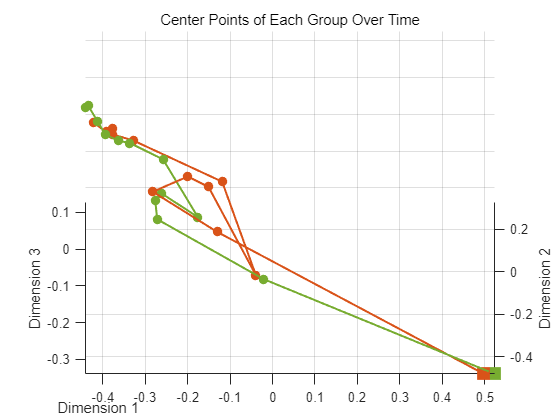

view(3);
output_filename = 'rotation_animation.gif'; % 输出文件名
angle_step = 5; % 每帧旋转的角度
num_frames = 360 / angle_step; % 总帧数
for i = 1:num_frames
    % 更新视角
    view(angle_step * i, 30); % 30 是俯仰角，可以调整
    drawnow; % 刷新图形
    
    % 捕获当前帧
    frame = getframe(gcf);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    
    % 保存为 GIF
    if i == 1
        imwrite(imind, cm, output_filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.1);
    else
        imwrite(imind, cm, output_filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.1);
    end
end


disp(['动图已保存为: ', output_filename]);

动图已保存为: rotation_animation.gif


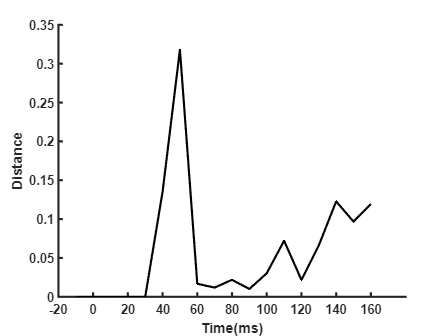

figure;
EC_EC0distance = [];
for t = 6:18
    point1 = squeeze(center_points(1,:,t));
    point2 = squeeze(center_points(2,:,t));
    EC_EC0distance(t) = pdist2(point1,point2);
end
plot(EC_EC0distance,'LineWidth',2,'Color','k');
xticklabels({'-20','0','20','40','60','80','100','120','140','160'});
xlabel('Time(ms)');
ylabel('Distance');
box off;
ax = gca;
ax.LineWidth = 2;

ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;
ax.XAxis.FontWeight = 'bold';

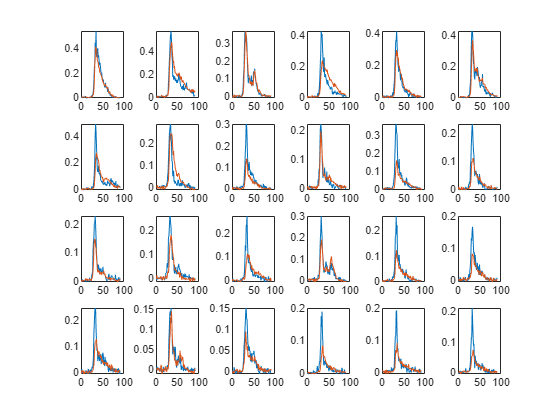

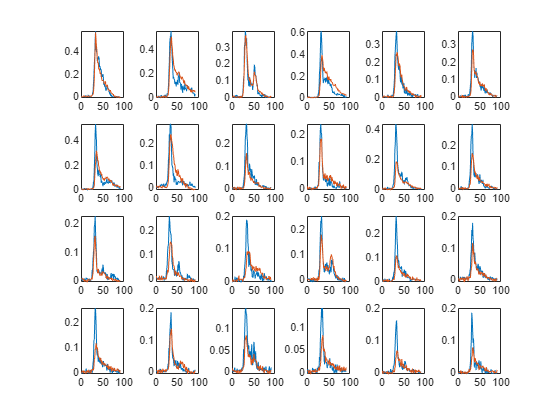

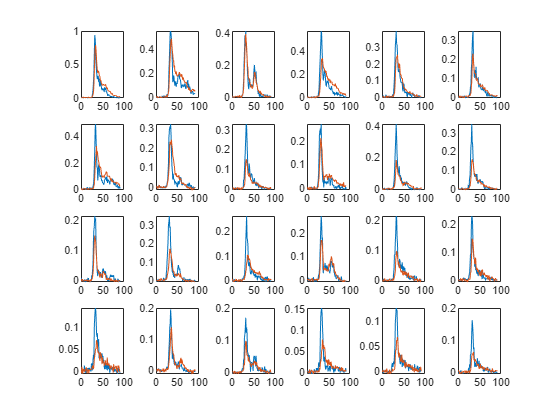

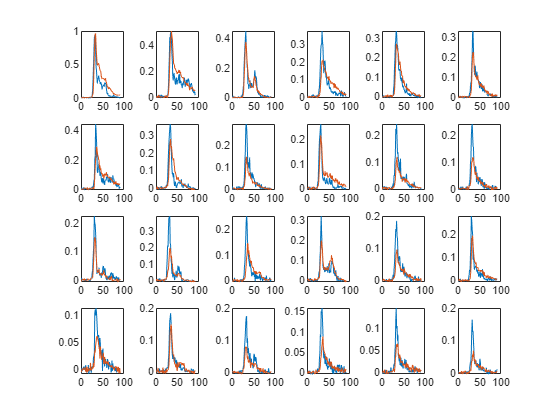

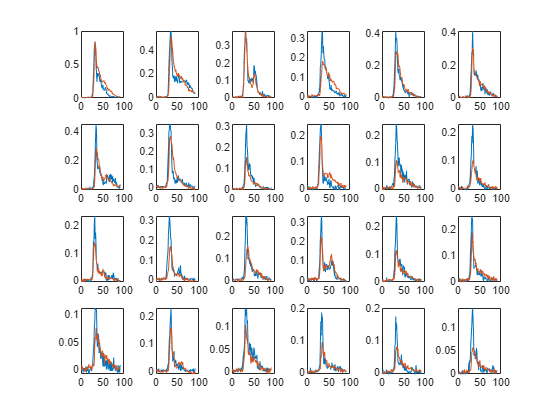

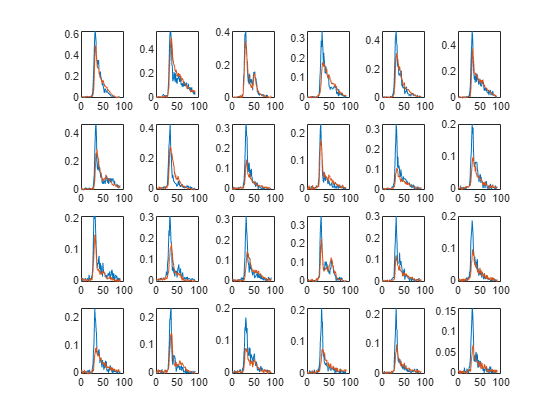

% 1.EC与EC0在早期也会存在差异，这一定程度上符合我们的解码。
% 2.拟合的数据与EC0无论是早期还是晚期都有很大的差别，可能需要做二者分离的解码。

for ori = 1:3:18
    figure;
    for coil = 1:coilnum
        subplot(4,6,coil)
        plot(squmean(correlationData(ori+18,coil,:),1)');
        hold on
        plot(squmean(correlationData(ori+72,coil,:),1)');
        hold off
    end
end

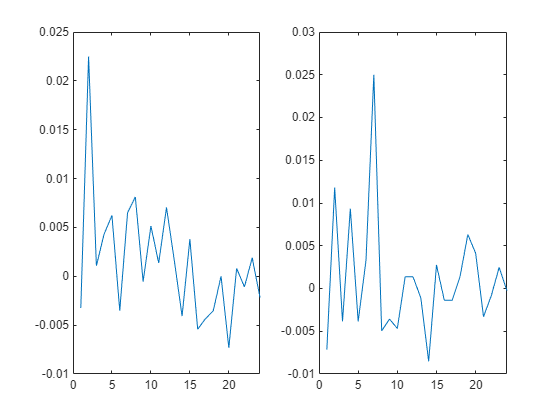


figure;
subplot(1,2,1)
plot(squeeze(correlationData(1,:,90))');
subplot(1,2,2)
plot(squeeze(correlationData(19,:,90))');

[a,p] = corr([squeeze(correlationData(1,:,33));squeeze(correlationData(19,:,33))]');
disp(a);

    1.0000    0.9083
    0.9083    1.0000



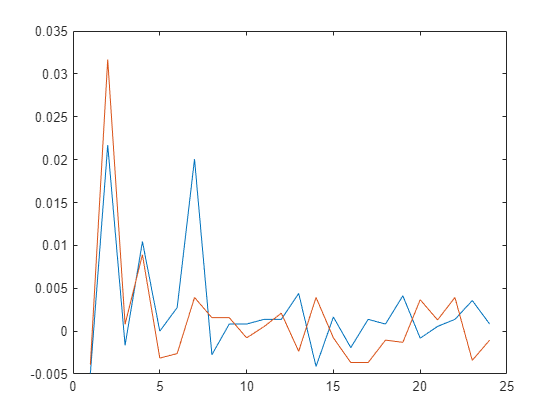


figure;
t1 = 1549;
t2 = 1567;
plot(correlationData_timebin(t1,:));
hold on 
plot(correlationData_timebin(t2,:));

[a,p] = corr([squeeze(correlationData_timebin(t1,:));squeeze(correlationData_timebin(t2,:))]');
disp(a);

    1.0000    0.6942
    0.6942    1.0000



% 合并数据
data = [dist_40ms_AB; dist_40ms_CD; dist_80ms_AB; dist_80ms_CD]';
group_names = {'40ms-AB', '40ms-CD', '80ms-AB', '80ms-CD'};

% 计算均值和标准差
mean_val = mean(data);
std_val = std(data);

% 绘制柱状图
figure;
bar(mean_val, 'grouped');
hold on;

% 绘制误差条
errorbar(1:4, mean_val, std_val, 'k.', 'LineWidth', 1.5);

% 绘制散点（显示原始数据点）
for i = 1:4
    x = i + 0.2 * (rand(1, 18) - 0.5);  % 添加轻微抖动避免重叠
    scatter(x, data(:, i), 40, 'k', 'filled', 'MarkerFaceAlpha', 0.6);
end

% 美化图形
set(gca, 'XTick', 1:4, 'XTickLabel', group_names, 'FontSize', 12);
ylabel('Distance', 'FontSize', 14);
title('Distance Comparison Across Conditions', 'FontSize', 16);
grid on;
hold off;



% 假设数据变量名为：
% MGvMGnv40（40ms条件1），MGvfitting40（40ms条件2）
% MGvMGnv80（80ms条件1），MGvfitting80（80ms条件2）


% 合并数据
data_40ms = [MGvMGnv40, MGvfittting40];  % 40ms两组数据（18×2）
data_80ms = [MGvMGnv80, MGvfittting80];  % 80ms两组数据（18×2）

% 计算均值和标准差
mean_40 = mean(data_40ms);
mean_80 = mean(data_80ms);
std_40 = std(data_40ms);
std_80 = std(data_80ms);

% 绘制分组柱状图
figure('Position', [100, 100, 800, 600]);
hold on;

% 定义颜色
colors = [0.2 0.6 0.8; 0.8 0.4 0.2]; % 两种条件的颜色

% 绘制40ms和80ms的bar
bar_positions = [1, 2]; % x轴位置：40ms在1，80ms在2
for i = 1:2
    % 绘制条件i的bar
    bar(bar_positions(i), mean_40(i), 'FaceColor', colors(i,:), 'BarWidth', 0.4, 'EdgeColor', 'none');
    bar(bar_positions(i)+0.5, mean_80(i), 'FaceColor', colors(i,:), 'BarWidth', 0.4, 'EdgeColor', 'none');
    
    % 添加误差条
    errorbar(bar_positions(i), mean_40(i), std_40(i), 'k.', 'LineWidth', 1.5);
    errorbar(bar_positions(i)+0.5, mean_80(i), std_80(i), 'k.', 'LineWidth', 1.5);
    
    % 绘制数据点（添加轻微抖动）
    x_jitter_40 = bar_positions(i) + 0.1*(rand(18,1)-0.5);
    x_jitter_80 = bar_positions(i)+0.5 + 0.1*(rand(18,1)-0.5);
    scatter(x_jitter_40, data_40ms(:,i), 40, colors(i,:), 'filled', 'MarkerEdgeColor', 'k');
    scatter(x_jitter_80, data_80ms(:,i), 40, colors(i,:), 'filled', 'MarkerEdgeColor', 'k');
end

% 设置x轴标签和美化
set(gca, 'XTick', [1.25, 2.25], 'XTickLabel', {'MGv MGnv', 'MGv MGvfitting'}, 'FontSize', 12);
ylabel('Value', 'FontSize', 14);
title('Comparison Between 40ms and 80ms', 'FontSize', 16);
xlim([0.5, 3]);


% 添加图例
% legend({'MGv MGnv', 'MGv MGvfitting'}, 'Location', 'northwest');

% 显著性检验和标注
p_values = zeros(1,2); % 存储两种条件的p值
for i = 1:2
    % t检验比较40ms和80ms
    [~, p_values(i)] = ttest2(data_40ms(:,i), data_80ms(:,i));
    
    % 标注显著性
    y_max = max([mean_40(i), mean_80(i)]) + 1.2*max([std_40(i), std_80(i)]);
    if p_values(i) < 0.001
        text(mean([bar_positions(i), bar_positions(i)+0.5]), y_max, '***', 'FontSize', 14, 'HorizontalAlignment', 'center');
    elseif p_values(i) < 0.01
        text(mean([bar_positions(i), bar_positions(i)+0.5]), y_max, '**', 'FontSize', 14, 'HorizontalAlignment', 'center');
    elseif p_values(i) < 0.05
        text(mean([bar_positions(i), bar_positions(i)+0.5]), y_max, '*', 'FontSize', 14, 'HorizontalAlignment', 'center');
    end
end

hold off;

% 显示p值
disp('显著性检验结果:');

显著性检验结果:


fprintf('Condition 1 (MGvMGnv): p = %.4f\n', p_values(1));

Condition 1 (MGvMGnv): p = 0.0000


fprintf('Condition 2 (Fitting): p = %.4f\n', p_values(2));

Condition 2 (Fitting): p = 0.5420


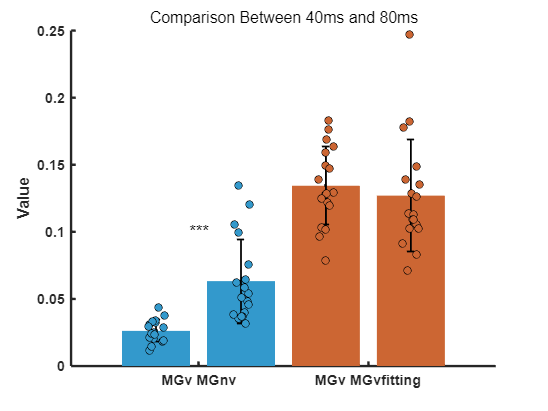

ax = gca;
ax.LineWidth = 2;

ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;

ax.XAxis.FontWeight = 'bold';